# **Lab 1. Introduction to system identification**

Through this lab we will learn the fundamentals of system identification and explore a series of useful commands from the System Identification Toolbox.

## 1. Preliminary operations

We have two datasets, each one containing data collected from an experiment.

clc, clearvars

### 1.1. Loading data

Let's start by loading the first dataset `data1`.

% Loading dataset
load data1

### 1.2. Creating an `iddata` object

Using the command `iddata` we now define an object to encapsulate input and output measurement data from the system we want to identify.

% Creating data object
data = iddata(Y,U,t)

data =

Time domain data set with 1000 samples.
Sample time: 1 seconds                  
                                        
Outputs      Unit (if specified)        
   y1                                   
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        
Data Properties


where `Y`, `U` and `t` are the elements of the dataset that have been loaded in the workspace. Let's plot the measurement data.

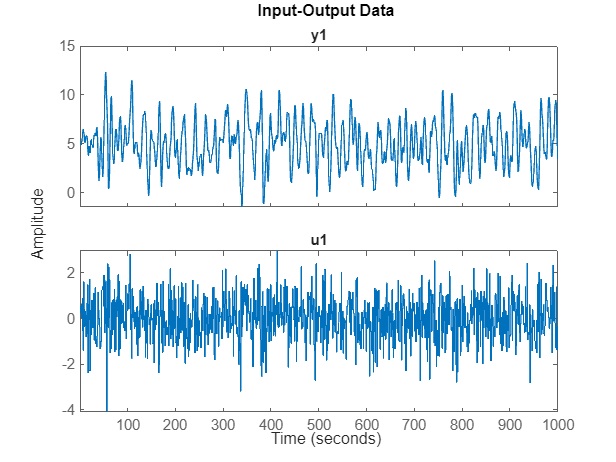

% Visualizing data
figure, plot(data)

### 1.3. Splitting data

We do not want to use all of our measurement data for the identification process. Instead, we want to store part of the data in order to perform validation on the model that we will identify. In this way we will be able to evaluate the generalization capabilities of the model and to understand if it behaves well.

Let's define an index that helps us split data in two parts.

% Splitting index
zc = 500;

Since we have 1000 samples, this means that we will use half of the data for the training and the other half of the data for the validation. Let's split data.

% Training set
train = data(1:zc);

% Validation set
valid = data((zc+1):1000);

### 1.4. Understanding data

Let's visualize the input and output data that will be used for the training.

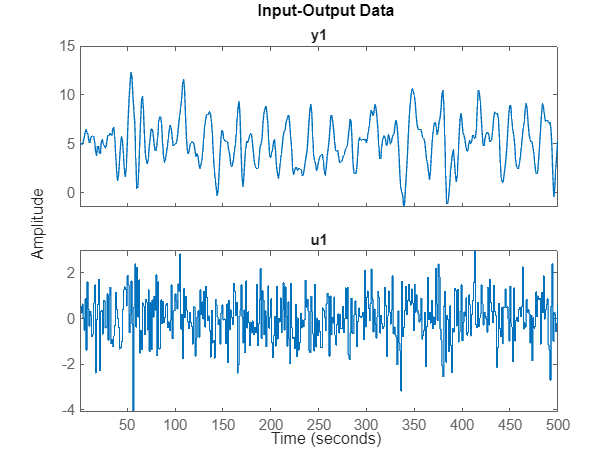

figure, plot(train)

As we can see, the input has zero mean while the output seems to have a mean of five. This is something that we have to keep in mind.

## 2. Identification

Once we loaded and visualized our data, we are ready to identify the system with an ARX model. Since we do not know which will be the best model, we consider different orders for the polynomials of our ARX model.

### 2.1. Training models

We will use the `arx` function to estimate the parameters of the ARX model using the datata contained in the training set. The inputs arguments are:

- the estimation data;

- a vector containing the polynomial orders of the ARX model and the delay between input and output.

Let's define a simple ARX model with 2 coefficients for each of the polynomials and the minimum time delay between input and output. As we can see, this is not a good model because the metrics are very high. 

% ARX(2,2)
m1 = arx(train, [2 2 1])

m1 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.73 z^-1 + 0.7598 z^-2               
                                                   
  B(z) = 0.01523 z^-1 + 0.0005962 z^-2             
                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=1
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "train". 
Fit to estimation data: 71.55% (prediction focus)
FPE: 0.4705, MSE: 0.4593                         
 
Model Properties


Maybe we underestimated the order of the system we want to identify. Let's try to increase the orders.

% ARX(3,3)
m2 = arx(train, [3 3 1]);

% ARX(5,5)
m3 = arx(train, [5 5 1]);

% ARX(10,10)
m4 = arx(train, [10 10 1]);

### 2.2. Comparing results

To understand the behaviour of the previous models, we compare the identified outputs with the measured output from the training set.

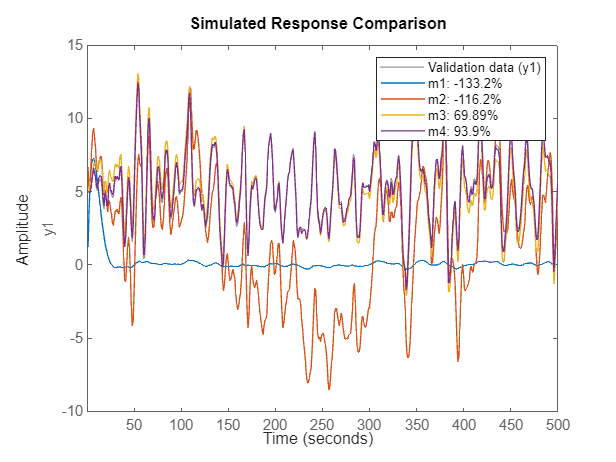

figure, compare(train, m1, m2, m3, m4)

We can say that:

- `m1` is not a good model and, as a matter of fact it fails to follow the measured output;

- `m2` is still not a good model because it looses the tracking of the measured output but still it is an improvement from the previous `m1` model;

- `m3` is a good model, even if in some cases it is a little bit imprecise;

- `m4` is a model that behaves very well, but maybe it can lead to overfitting.

### 2.3. Fitness function

The fit function that appears in the legend of the previous plot is defined as:


$$\text{FIT} = 100\left(1 - \frac{y(k)-\hat{y}(k)}{y(k) - \mathbb{E}[y(k)]} \right)$$


This index measures the prediction error compared to the variability of the signal.

## 3. Validation

The only two ARX models that showed a proper behaviour are `m3` and `m4`.

### 3.1. Comparing results

Let's understand their generalization capabilities by evaluating their behaviour on the unseen data from the validation set.

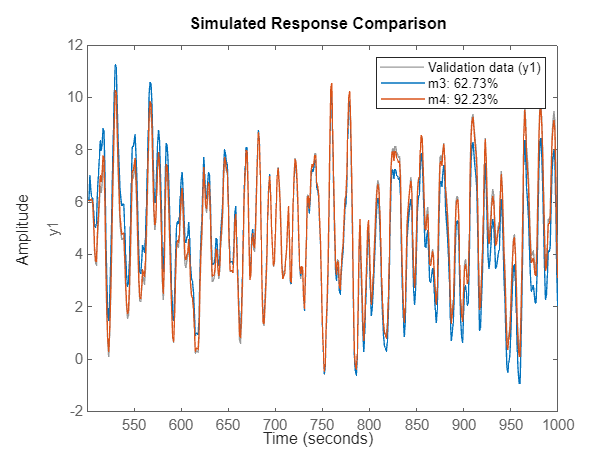

figure, compare(valid, m3, m4)

Results are coherent because both the models mantained approximately the same accuracy.

## 4. Improving results

At the end of our identification process, we can conclude that the results given by models `m1` and `m2` are not so good. There are several things that can be done to improve the identification process.

### 4.1. Understanding what can be done

Through the command `advice` we can perform an analysis on our data in order to check the peculiarities of the input and output measurements data in order to understand how to improve the identification results.

advice(data)

General data characteristics:
-----------------------------
This is a time domain data set with 1 input(s) and 1 output(s), 1000 samples 
and 1 experiment(s).

All inputs in the data have been denoted as 'zero order hold' ('zoh'), i.e. 
they are assumed to be piecewise constant over the sample time.
If the input is a sampled continuous signal and you plan to build or convert to 
continuous-time models, it is recommended to mark the InterSample property as 
'First order hold': Data.InterSample = 'foh' or Data.InterSample = 
{'foh','foh', ...} for multi-input signals.

Some inputs and/or outputs have non-zero means. It is generally recommended to 
remove the means by DAT = DETREND(DAT), except in the following cases:
1. The signals are measured relative to a level that corresponds to a physical 
equilibrium. This could e.g. be the case if step responses are recorded from an 
equilibrium point. In this case, it is advisable to remove the equilibrium 
values rather than data means. You may

### 4.2. Detrending data

It can be noticed that the output has a significant negative offset that can influence the identification. For this reason, we use the command `detrend` in order to remove the offset from the data.

% Detrending training set
train_det = detrend(train,0);

% Detrending validation set
valid_det = detrend(valid,0);

We can explore the results of the `detrend` command by comparing the two sets.

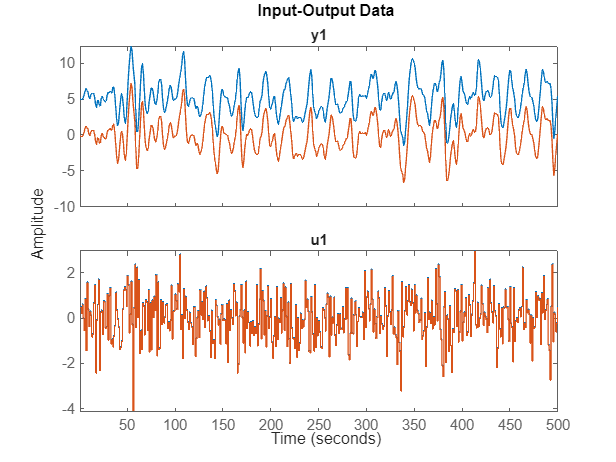

figure, plot(train,train_det)

As we can see, now also the output has zero mean. It's important to remember that if a model is trained with detrended training data, then also its validation needs to be performed on detrended validation data.

### 4.3. Estimating the delay of the system

At the beginning of the process we assumed that the delay of the system was equal to one step. This may be not true, and for this reason we need to estimate the real delay of the system. We can use two methods.

The first one is to compute the impulse response of the system and check the first time sample in which the impulse response is not equal to zero. For our purposes we can use the well-known `impulse` command.

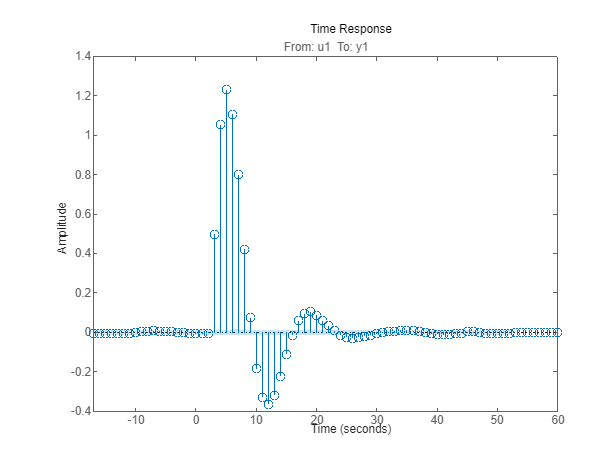

% Impulse response
impulse(train_det,'sd',3,'fill')

The first sample to be different from zero is the one at the time sample 3. This means that there is a delay of three samples between the input and the output.

### 4.4. Repeating the process

Now that we understood how to improve the identification process, let's consider again the two models that previously performed the worst on the data to see if we can really improve their performances.

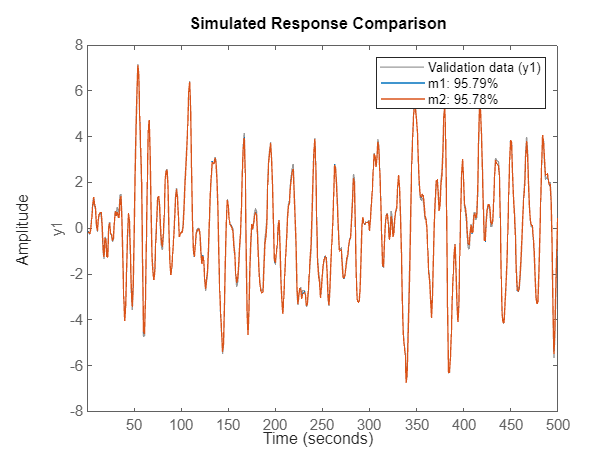

% ARX(2,2)
m1 = arx(train_det, [2 2 3]);

% ARX(3,3)
m2 = arx(train_det, [3 3 3]);

% Comparing results
figure, compare(train_det, m1, m2)

As we can see the models performed very well on the training set. Let's validate their behaviour

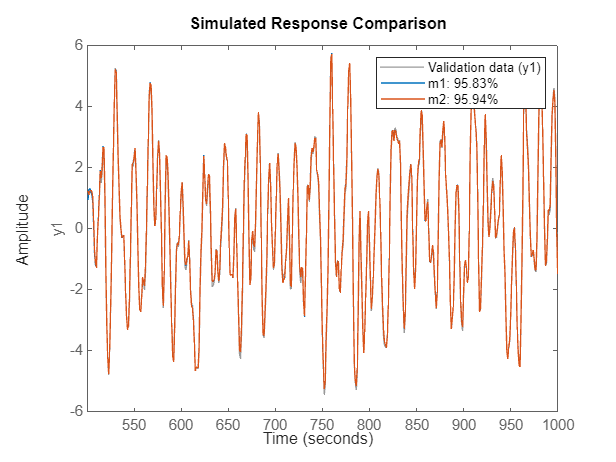

% Comparing results
compare(valid_det, m1, m2)

With these simple improvements we were able to improve the behaviour of the models `m1` and `m2`.

## 5. Whiteness analysis

To check if the identification we have done is actually correct we need to look at the residual of the prediction error of the identified model. If the error is equal to white noise, this means that our model identified everything he could from the data, so it would be a perfect model. If not, there is something that we need to change. 

### 5.1. Whiteness test

Let us now consider one of our best models, for example `m2`.

% Choosing model
m = m2;

White noise has an autocorrelation that is an impulse and a cross-correlation that is always equal to zero.

For this reason we want to assess the autocorrelation of the prediction error and the cross-correlation between the input and the prediction error to see if the prediction error reflects the characteristics of white noise. This test is called whiteness test. To evaluate if the prediction error is white noise or not we can use the function `resid`, which computes the autocorrelation of the prediction error and the cross-correlation between the input and the prediction error and plots them.

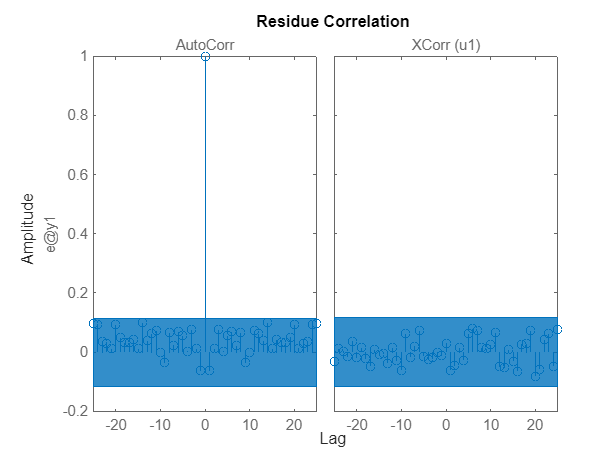

% Whiteness test
resid(m,valid_det,'corr')

Again, the blue band represents uncertainty. We can see that the autocorrelation is completely impulsive and that the cross-correlation is always bounded. Since the prediction error is white noise, the model is perfect, meaning that all the important information about the dynamics of the system have been identified correctly.

Let us now consider our worst model `m1` before detrending.

% Choosing model
m = arx(train, [2 2 1]);

 We want to repeat the whiteness test.

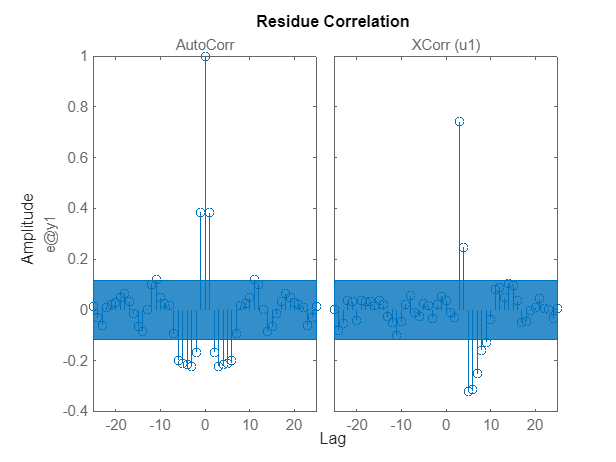

% Whiteness test
resid(m,valid_det, 'corr')

We can see that the autocorrelation is not impulsive, instead, there are several samples; the cross-correlation is also not bounded, meaning that samples depend on each other at any time instant. These observations tell us that the prediction error is not white noise, so the model is not good.

### 5.2. Model error identification

Let us now consider one of our best models, for example `m3`.

% Choosing model
m = m2;

Another possible test to evaluate if the model is good is the model error identification. We treat the measured input as the input and the prediction error as the output of a system. If the dynamics of this system is neglectable, there is nothing left unexplained in the data meaning that the identified model behaved correctly.

We use again the function `resid` but this time we change its attribute.

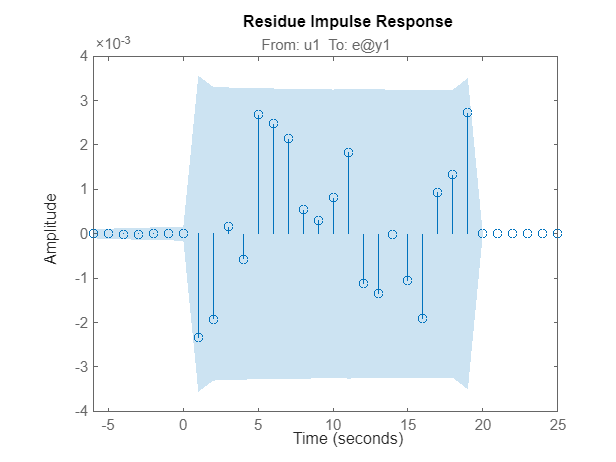

% Model error identification
resid(m, valid_det, 'ir')

Since the response is always bounded inside the uncertainty area, we can say that the model is good.

### 5.3. Checking frequency response

Last tests we can do are in the frequency domain. First, we use again the function `resid` changing its attribute in order to compute and visualize the frequency response.

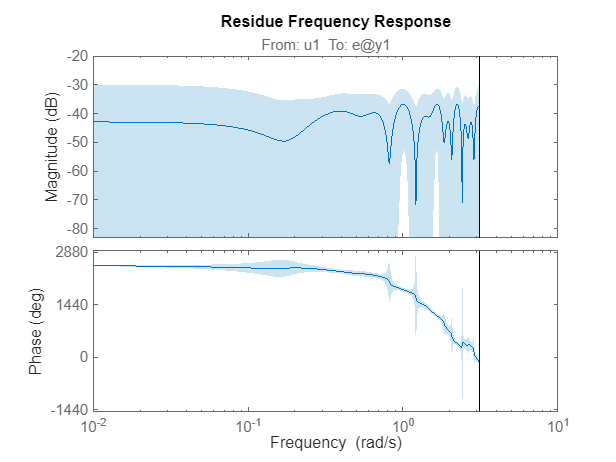

% Frequency response test
resid(m, valid_det, 'fr')

Uncertainty area is quite large. The frequency response is always bounded meaning the model is good.

### 5.4. Checking Bode diagram

An alternative method in the frequency domain is to analyze the spectrum of the prediction error. We first need to compute the error (this task was directly done inside the `resid` function) using the function `pe`.

% Prediction error
e = pe(m, valid_det);

Then we use the function `spa` in order to evaluate the prediction error in the frequency domain. As a matter of fact, the output of this function is not anymore an `iddata` object but an `idrdf` object. 

% Spectral analysis
G = spa(e);

Finally we can evaluate the Bode diagram.

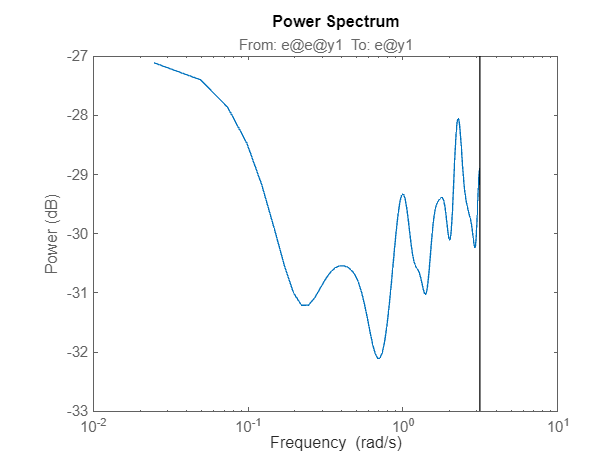

% Bode diagram
figure, bode(G,'sd',3,'fill')

We can see the power of the prediction error decreases but does not reach steady state.